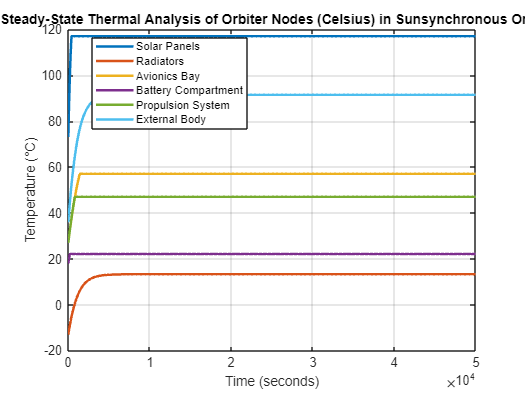

clear; clc;

sBoltzmann = 5.670e-8; 
SolarFlux = 1400; 
Albedo = 0.25; 
T_mars = 2.7; 

nodes = {'Solar Panels', 'Radiators', 'Avionics Bay', 'Battery Compartment', 'Propulsion System', 'External Body'};
Area = [2.0; 0.9; 0.8; 0.5; 1.0; 1.5]; 
absorb = [0.8; 0.2; 0.3; 0.3; 0.4; 0.5]; 
emissivity = [0.8; 0.9; 0.6; 0.7; 0.8; 0.85];

%power allocation
power = [5; 5; 10; 5; 8; 0];

% active TCS
kapton_patch_heaters = [5; 0; 3; 4; 0; 3];
radioisotope_heaters = [0; 0; 4; 4; 0; 0];
ricor_cryocoolers = [1; 1; 2; 0; 1; 4];
thermal_sensors = [1; 1; 1; 1; 1; 0];

% Total power with active TCS
power = power + kapton_patch_heaters + radioisotope_heaters + ricor_cryocoolers + thermal_sensors;

Q_absorbRadiation = Area .* absorb .* SolarFlux; 
Q_reflectRadiation = Area .* absorb .* SolarFlux * Albedo; 
Q_planetary_IR = Area .* emissivity .* sBoltzmann .* T_mars^4; 

massNode = [10; 5; 8; 6; 12; 15]; 
c_p = 900; 
C = massNode * c_p; 

T_initial = [349; 263; 303; 294; 303; 312];  

% updated ranges
op_range = [123.15 373.15;   % Solar Panels (-150 to 100)
            243.15 313.15;   % Radiators (-30 to 40)
            263.15 323.15;   % Avionics Bay (-10 to 50)
            273.15 288.15;   % Battery (0 to 15)
            253.15 313.15;   % Propulsion System (-20 to 40)
            153.15 378.15];  % External Body (-120 to 105)

survival_range = [93.15 393.15;    % Solar Panels (-180 to 120)
                  243.15 323.15;   % Radiators (-30 to 50)
                  253.15 333.15;   % Avionics Bay (-20 to 60)
                  253.15 298.15;   % Battery (-20 to 25)
                  243.15 323.15;   % Propulsion System (-30 to 50)
                  133.15 393.15];  % External Body (-140 to 120)

time_span = linspace(0, 50000, 500);

thermalBalance = @(t, T) ((Q_absorbRadiation + Q_reflectRadiation + Q_planetary_IR + power) - ...
                          (Area .* emissivity .* sBoltzmann .* (T.^4))) ./ C;
thermalBalanceCol = @(t, T) reshape(thermalBalance(t, T), [], 1); 

[t, T] = ode45(thermalBalanceCol, time_span, T_initial);

for i = 1:length(nodes)
    T(:, i) = max(min(T(:, i), survival_range(i,2)), survival_range(i,1));
end

T_Celsius = T - 273.15;

figure;
plot(t, T_Celsius-3, 'LineWidth', 2);
xlabel('Time (seconds)');
ylabel('Temperature (°C)');
legend(nodes, 'Location', 'Best');
title('Steady-State Thermal Analysis of Orbiter Nodes (Celsius) in Sunsynchronous Orbit');
grid on;


for i = 1:length(nodes)
    Tmin = min(T(:, i));
    Tmax = max(T(:, i));

    if Tmin < survival_range(i,1) || Tmax > survival_range(i,2)
        fprintf('WARNING: %s out of SURVIVAL range (%.2f°C to %.2f°C), Range: %.2f°C to %.2f°C\n', ...
            nodes{i}, survival_range(i,1)-273.15, survival_range(i,2)-273.15, Tmin-273.15, Tmax-273.15);
    elseif Tmin < op_range(i,1) || Tmax > op_range(i,2)
        fprintf('ALERT: %s out of OPERATIONAL range (%.2f°C to %.2f°C), Range: %.2f°C to %.2f°C\n', ...
            nodes{i}, op_range(i,1)-273.15, op_range(i,2)-273.15, Tmin-273.15, Tmax-273.15);
    end
end

ALERT: Solar Panels out of OPERATIONAL range (-150.00°C to 100.00°C), Range: 75.85°C to 120.00°C
ALERT: Avionics Bay out of OPERATIONAL range (-10.00°C to 50.00°C), Range: 29.85°C to 60.00°C
ALERT: Battery Compartment out of OPERATIONAL range (0.00°C to 15.00°C), Range: 20.85°C to 25.00°C
ALERT: Propulsion System out of OPERATIONAL range (-20.00°C to 40.00°C), Range: 29.85°C to 50.00°C
